### **Método das Secantes**


$$x^{k+1} = \frac{x^{k-1}f(x^{k})-x^{k}f(x^{k-1})}{f(x^{k})- f(x^{k-1})$$


VVamos encontrar o zero da função $f(x) = -0.5x^{2}+2.5x+4.5$ no intervalo de $[-2.5,0]$utilizando o método das Secantes, com  chute inicial $x^{0} = -2$ e $x^{1} = 0$ erro relativo igual ou menor que $10^{-4}$.

**Graficamente, **

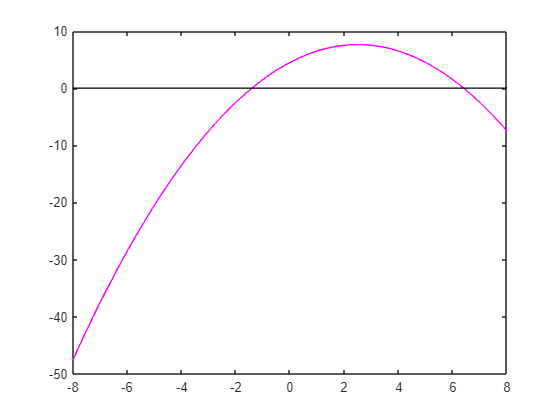

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

**Implementação do Newton-Raphson:**

format long
x0 = -2;
x1 = 0;
 tol = 10^-4  %tolerancia 

tol =      1.000000000000000e-04


 k = 0;  %numero de interações
 er_rel = 10  %erro relativo inicial 

er_rel =     10


 while ( er_rel > tol)
     k = k+1; 
     x= (x0*fun(x1)-x1*fun(x0))/(fun(x1)- fun(x0)) ;  %Atualização pelo metodo das Secantes 
     xk(k, : ) = x;
     fk(k, : ) = fun(x);
     er_relk(k, :) = er_rel;
     x0 = x1;
     x1=x; 
     er_rel = abs(x1-x0)/abs(x1);
 end
 [xk, fk, er_relk]

ans =   -1.285714285714286   0.459183673469387  10.000000000000000
  -1.431818181818182  -0.104597107438017   1.000000000000000
  -1.404711821623896   0.001612795035300   0.102040816326531
  -1.405123431107836   0.000005493906281   0.019296740994854
  -1.405124838027727  -0.000000000290541   0.000292934752085


**Mudar o chute unicial **

format long
x0 = -1; %chute inicial 
x1 = 0;
 tol = 10^-4  %tolerancia

tol =      1.000000000000000e-04


 k = 0;  %numero de interações
 er_rel = 10  %erro relativo inicial 

er_rel =     10


 while ( er_rel > tol)
     k = k+1; 
     x= (x0*fun(x1)-x1*fun(x0))/(fun(x1)- fun(x0)) ;  %Atualização pelo metodo das Secantes 
     xk(k, : ) = x;
     fk(k, : ) = fun(x);
     er_relk(k, :) = er_rel;
     x0 = x1;
     x1=x; 
     er_rel = abs(x1-x0)/abs(x1);
 end
 [xk, fk, er_relk]

ans =   -1.500000000000000  -0.375000000000000  10.000000000000000
  -1.384615384615385   0.079881656804734   1.000000000000000
  -1.404878048780488   0.000963712076146   0.083333333333333
  -1.405125487740257  -0.000002537499292   0.014423076923077
  -1.405124837932795   0.000000000080183   0.000176097410465


**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = -0.5*x.^2 +2.5*x + 4.5;
end
